# Reciprocal Space Tomography on GaMo4S8

## Load raw data

load('Cartesian_mesh_Lab.mat','Xc','Yc','Zc'); %meshgrid in [Qx,Qy,Qz] order in nm^-1 units 
load('GMS_intensity_raw.mat','I_cart_cartint'); %Raw intensity data in [Qx,Qy,Qz] order in arbitrary units

## Post processing

Rmax=0.4; %forward scattered intensity
I_cart_cartint(Xc.^2+Yc.^2+Zc.^2<Rmax^2)=NaN; %masking noise within the sphere with r<0.03
I_cart=I_cart_cartint;

## Transform coordinate system from [11-2,111,1-10] to [100,010,001]

T=[1/sqrt(6)*[1;1;-2],1/sqrt(3)*[1;1;1],1/sqrt(2)*[1;-1;0]];
A=[Xc(:),Yc(:),Zc(:)]*T';
Xt=reshape(A(:,1),size(Xc));
Yt=reshape(A(:,2),size(Yc));
Zt=reshape(A(:,3),size(Zc));

## Show original data without smoothing or symmetrizing

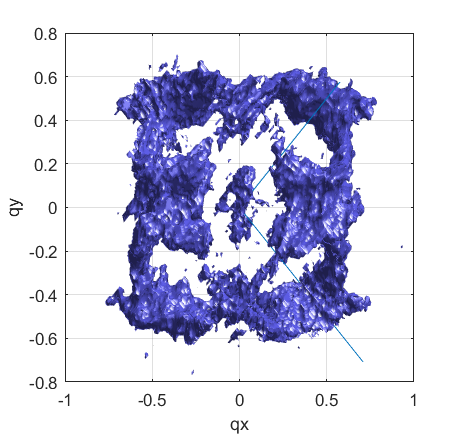

thr=3.6;    %Intensity threshold for visualization : best option: 3.6
alpha=1; % no transparency
col=[0.4,0.4,1]; %blue

figure(2)
wx=9.67;
wy=9.22;
cla
hold on
%Plot_Slicing_Planes;
Plot_RST(Xt,Yt,Zt,I_cart,thr,col,alpha); %Custom function to plot the data with intensities above thr
v2=T'*eye(3);
line([0,v2(1,1)],[0,v2(1,2)],[0,v2(1,3)])
line([0,v2(2,1)],[0,v2(2,2)],[0,v2(2,3)])
line([0,v2(3,1)],[0,v2(3,2)],[0,v2(3,3)])
%daspect([1 1 1]) 
set(gcf,'Units','centimeters');
set(gcf, 'Position', [1.12 11.34 wx wy]);
%view(-162,47); %view1
%view(117,52); %top view
axis square
xlabel('qx')
ylabel('qy')
zlabel('qz')

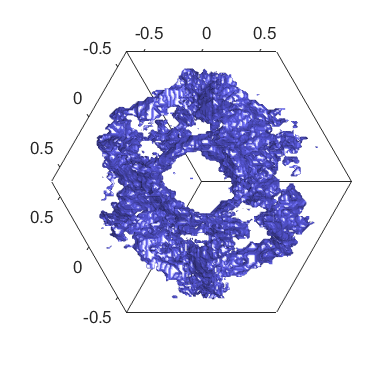


figure(3)
Pos=[5.8208   12.2978    8.2338    8.0010];
cla
hold on
Plot_RST(Xt,Yt,Zt,I_cart,thr,col,alpha);
set(gcf,'Units','centimeters');
set(gcf, 'Position', Pos);
view(1/sqrt(3)*[1,1,1])
camup([1,-1,0])
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square
grid off

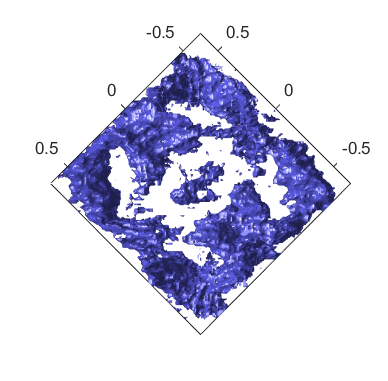


figure(4)
Pos=[14.0547   12.2555    8.2127    8.0645];
cla
hold on
Plot_RST(Xt,Yt,Zt,I_cart,thr,col,alpha);
set(gcf,'Units','centimeters');
set(gcf, 'Position', Pos);
%view(-54.7,0);
view([0,0,1])
camup([1,-1,0])
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square
grid off

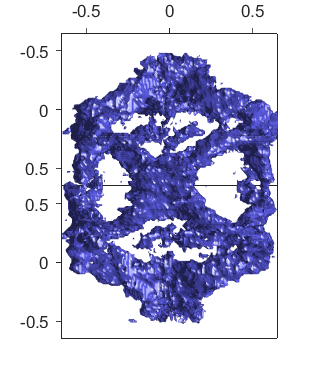


figure(5)
Pos=[22.2038   12.2132    6.9215    8.0645];
cla
hold on
Plot_RST(Xt,Yt,Zt,I_cart,thr,col,alpha);
set(gcf,'Units','centimeters');
set(gcf, 'Position', Pos);
%view(+35.2,0);
view([1,1,0])
camup([1,-1,0])
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square
grid off

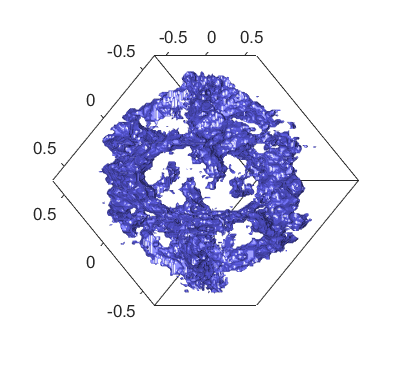


figure(6)
Pos=[29.1888   12.3825    8.4032    7.9163];
cla
hold on
Plot_RST(Xt,Yt,Zt,I_cart,thr,col,alpha);
view(1/sqrt(6)*[1,1,2])
camup([1,-1,0])
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square
set(gcf,'Units','centimeters');
set(gcf, 'Position', Pos);
grid off

%}

## Perform Gaussian smoothing to erase noise

%Applying 3D Gaussian filter to smooth noisy data. Takes some time to run,
%therefore it has been saved to GMS_Cart_intensity_gauss_31_3.mat
%====================================================
%I_cart=smooth3(I_cart_cartint,'gaussian',31,3); 
%save('GMS_Cart_intensity_gauss_31_3.mat','I_cart')
%====================================================
Int2=load('GMS_intensity_gauss_31_3.mat','I_cart'); %load smoothed data
I_cart=Int2.I_cart;

## RST images after Gaussian smoothing (31,3)

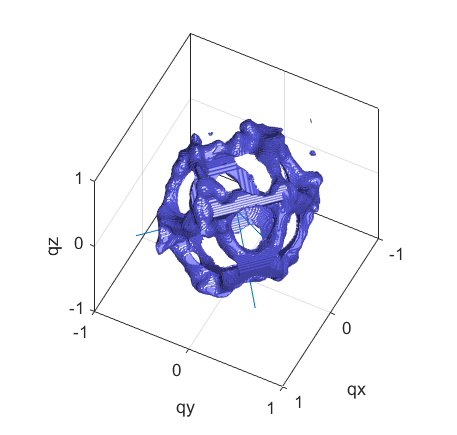

%==========================================================================
thr=1.7;    %Intensity threshold for visualization : best option: 1.7
figure(22)
wx=9.67;
wy=9.22;
cla
hold on
%Plot_Slicing_Planes;
Plot_RST(Xt,Yt,Zt,I_cart,thr,col,alpha); 
v2=T'*eye(3);
line([0,v2(1,1)],[0,v2(1,2)],[0,v2(1,3)])
line([0,v2(2,1)],[0,v2(2,2)],[0,v2(2,3)])
line([0,v2(3,1)],[0,v2(3,2)],[0,v2(3,3)])
%daspect([1 1 1]) 
set(gcf,'Units','centimeters');
set(gcf, 'Position', [1.12 11.34 wx wy]);
%view(-162,47); %view1
view(117,52); %top view
axis square
xlabel('qx')
ylabel('qy')
zlabel('qz')

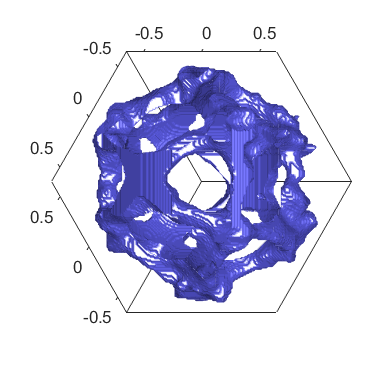


figure(23)
Pos=[5.8208   12.2978    8.2338    8.0010];
cla
hold on
Plot_RST(Xt,Yt,Zt,I_cart,thr,col,alpha);
set(gcf,'Units','centimeters');
set(gcf, 'Position', Pos);
view(1/sqrt(3)*[1,1,1])
camup([1,-1,0])
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square
grid off

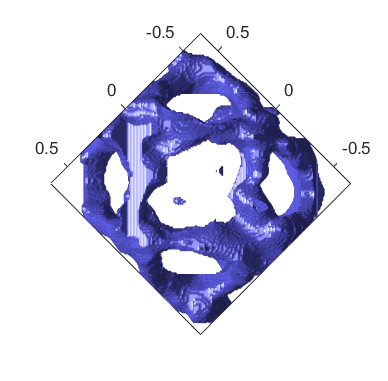



figure(24)
Pos=[14.0547   12.2555    8.2127    8.0645];
cla
hold on
Plot_RST(Xt,Yt,Zt,I_cart,thr,col,alpha);
set(gcf,'Units','centimeters');
set(gcf, 'Position', Pos);
%view(-54.7,0);
view([0,0,1])
camup([1,-1,0])
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square
grid off

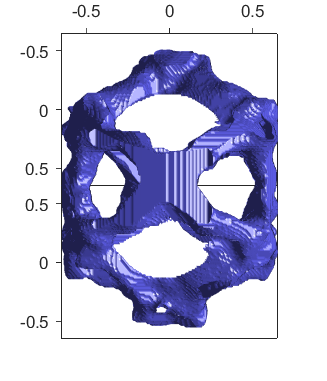


figure(25)
Pos=[22.2038   12.2132    6.9215    8.0645];
cla
hold on
Plot_RST(Xt,Yt,Zt,I_cart,thr,col,alpha);
set(gcf,'Units','centimeters');
set(gcf, 'Position', Pos);
%view(+35.2,0);
view([1,1,0])
camup([1,-1,0])
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square
grid off

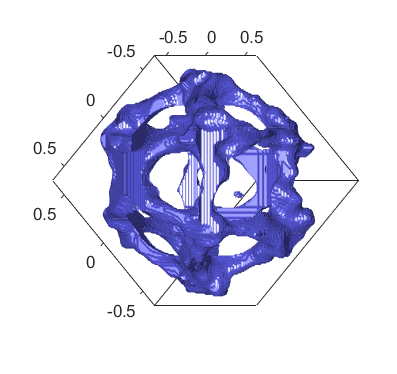


figure(26)
Pos=[29.1888   12.3825    8.4032    7.9163];
cla
hold on
Plot_RST(Xt,Yt,Zt,I_cart,thr,col,alpha);
view(1/sqrt(6)*[1,1,2])
camup([1,-1,0])
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square
set(gcf,'Units','centimeters');
set(gcf, 'Position', Pos);
grid off

%==========================================================================



## Plot intensity in slicing planes after the 3D smoothing (not ready yet)

%{
figure(26)
res=1;
zmin=-85;
zmax=85;
rmin=-85;
rmax=85;

## Rocking around 111

for i=1:11
    subplot(2,6,i)
    cla
    phi=-12+i*2;
    [X2D,Z2D,I2D]= Slicing_plane_intensity(Xc,Yc,Zc,I_cart,zmin,zmax,rmin,rmax,res,phi);
    A=[X2D,Z2D,I2D];
    save(['X2D_' num2str(phi) '.mat'], 'X2D')
    save(['Z2D_' num2str(phi) '.mat'], 'Z2D')
    save(['I2D_' num2str(phi) '.mat'], 'I2D')
    pcolor(X2D,Z2D,I2D);
end
%}


%==========================================================================

## Perform symmetries of Td

%This function applies the Td symmetri operations to the original
%volumetric data. It takes several hours to run, therefore data has been
%saved to C2_100.mat, ...
%==================================
%Perform_symmetry_operations 
%==================================

## Load symmetry transformed data

%{
WorkingDir = fullfile(pwd);
p = genpath(WorkingDir);
addpath(p)
load('C2_100.mat'); load('C2_010.mat'); load('C2_001.mat');
load('C3_111.mat'); load('C32_111.mat'); load('C3_1m1m1.mat'); load('C32_1m1m1.mat'); load('C3_m1m11.mat'); load('C32_m1m11.mat'); load('C3_m11m1.mat'); load('C32_m11m1.mat');
load('S4_100.mat'); load('S43_100.mat'); load('S4_010.mat'); load('S43_010.mat'); load('S4_001.mat'); load('S43_001.mat');
load('m_110.mat'); load('m_1m10.mat'); load('m_101.mat'); load('m_10m1.mat'); load('m_011.mat'); load('m_01m1.mat');
%}

## Average symmetry transformed volume data

%{
I_av=(permute(I_cart_cartint,[2,1,3])+...
    I_C2_100+I_C2_010+I_C2_001+...
    I_C3_111+I_2C3_111+I_C3_1m1m1+I_2C3_1m1m1+I_C3_m1m11+I_2C3_m1m11+I_C3_m11m1+I_2C3_m11m1+...
    I_S4_100+I_3S4_100+I_S4_010+I_3S4_010+I_S4_001+I_3S4_001+...
    I_m_110+I_m_1m10+I_m_101+I_m_10m1+I_m_011+I_m_01m1)/24;  
I_av=permute(I_av,[2,1,3]);
%}
%Xc=permute(Xc,[2,1,3]);
%Yc=permute(Yc,[2,1,3]);
%Zc=permute(Zc,[2,1,3]);
%==========================================================================

load('GMS_intensity_fullsymmetrized.mat','I_av') %load fully symmetrized data

## RST images after Symmetrizing

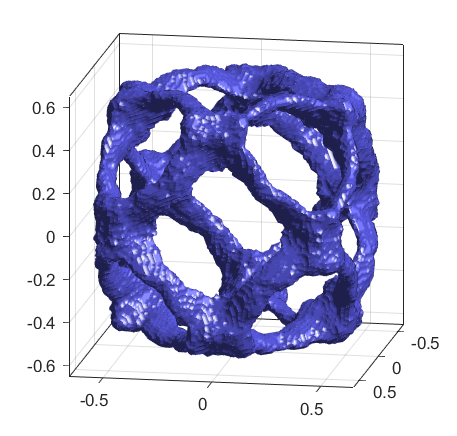

%==========================================================================
thr=3.6; %Intensity threshold for visualization : best option: 3.6
figure(32)
wx=9.67;
wy=9.22;

cla
hold on
%%Plot_Slicing_Planes;
Plot_RST(Xt,Yt,Zt,I_av,thr,col,alpha);
set(gcf,'Units','centimeters');
%daspect([1 1 1]) 

set(gcf, 'Position', [1.1007 1.7357 wx wy]);
%view(-162,47); %view1
%view(117,52); %top view
view(100,13);
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square

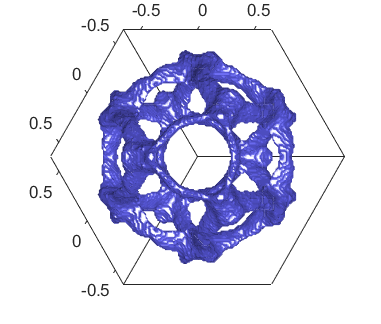


figure(33)
Pos=[5.9690    3.1750    8.0645    6.8580];
cla
hold on
Plot_RST(Xt,Yt,Zt,I_av,thr,col,alpha);
view(1/sqrt(3)*[1,1,1])
camup([1,-1,0])
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square
set(gcf,'Units','centimeters');
set(gcf, 'Position', Pos);
grid off

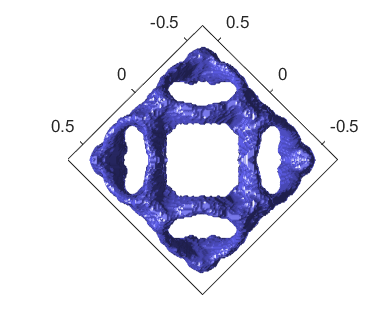


figure(34)
Pos=[14.1817    3.1327    8.2762    7.0273];
cla
hold on
Plot_RST(Xt,Yt,Zt,I_av,thr,col,alpha);
view([0,0,1])
camup([1,-1,0])
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square
set(gcf,'Units','centimeters');
set(gcf, 'Position', Pos);
%axis square
grid off

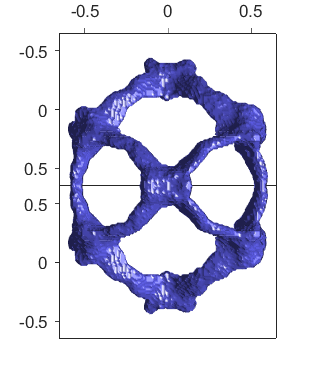


figure(35)
Pos=[22.7753    2.7093    6.8792    8.0645];
cla
hold on
Plot_RST(Xt,Yt,Zt,I_av,thr,col,alpha);
view(1/sqrt(2)*[1,1,0])
camup([1,-1,0])
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square
set(gcf,'Units','centimeters');
set(gcf, 'Position', Pos);
%axis square
grid off

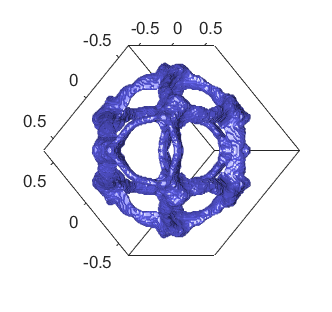



figure(36)
Pos=[29.9297    3.5348    7.0273    6.6040];
cla
hold on
Plot_RST(Xt,Yt,Zt,I_av,thr,col,alpha);
view(1/sqrt(6)*[1,1,2])
camup([1,-1,0])
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square
set(gcf,'Units','centimeters');
set(gcf, 'Position', Pos);
%axis square
grid off


%==========================================================================




## =======Scatter3 plots========


%Old visualization
%{
thr_low=4.2;
thr_high=6;

ind=find(I_av<thr_high & I_av>thr_low)
[K,L,M]=ind2sub([151,151,151],ind);
vx=Xc(1,K,1); %ndgrid: 1st index K, meshgrid: 2nd index K
vy=Yc(L,1,1); %ndgrid: 2nd index L, meshgrid: 1st index L
vz=Zc(1,1,M);

figure(28)
cla
scatter3(vx,vy,vz,2,I_av(ind))
view()
%}

%{
figure(23)
thr_low=4.2;
thr_high=6;

ind=find(I_cart_cartint<thr_high & I_cart_cartint>thr_low);
[K,L,M]=ind2sub([151,151,151],ind);
vx=Xc(K,1,1); %ndgrid: 1st index K, meshgrid: 2nd index K
vy=Yc(1,L,1); %ndgrid: 2nd index L, meshgrid: 1st index L
vz=Zc(1,1,M);

subplot(1,3,1)
cla
scatter3(vx,vy,vz,1,I_cart_cartint(ind))
daspect([0.75 0.75 1])
phi=54.7*pi/180;
view([cos(phi)+sin(phi),sin(phi)-cos(phi),0])

subplot(1,3,2)
cla
scatter3(vx,vy,vz,1,I_cart_cartint(ind))
daspect([0.75 0.75 1])
view([1,1,0])  


subplot(1,3,3)
cla
scatter3(vx,vy,vz,1,I_cart_cartint(ind))
daspect([0.75 0.75 1])
view([1,-1,0])

size=75;
[v1t,v2t,v3t,v4t]=Hexagons(size,0);

figure(24)
ax1=subplot(1,2,1);
cla
scatter3(vx,vy,vz,2,I_cart_cartint(ind))
view([1,1,1])

hold on
plot3(v1t(:,1),v1t(:,2),v1t(:,3),'Color','r','LineWidth',1.5)
plot3(v2t(:,1),v2t(:,2),v2t(:,3),'Color','b','LineWidth',1.5)
plot3(v3t(:,1),v3t(:,2),v3t(:,3),'Color','g','LineWidth',1.5)
plot3(v4t(:,1),v4t(:,2),v4t(:,3),'Color','y','LineWidth',1.5)
axis square
axis vis3d

ax2=subplot(1,2,2);
cla
hold all
plot3(v1t(:,1),v1t(:,2),v1t(:,3),'Color','r')
plot3(v2t(:,1),v2t(:,2),v2t(:,3),'Color','b')
plot3(v3t(:,1),v3t(:,2),v3t(:,3),'Color','g')
plot3(v4t(:,1),v4t(:,2),v4t(:,3),'Color','y')


text(0,0,size,'(1,-1,0)')
text(size,0,0,'(1,1,-2)')
text(0,size,0,'(1,1,1)')
box on
view([1,1,1])
axis square
axis vis3d
hlink = linkprop([ax1,ax2],{'CameraPosition','CameraUpVector'}); 
rotate3d on
%}
%{
figure(312231)
cla
scatter3(vx,vy,vz,2,I_cart_cartint(ind))
%rotating in 3D
alpha=0:0.1:6.28;
grid off
axis on
for i=1:numel(alpha)
    vw=cos(alpha(i))*[1,0,0]+sin(alpha(i))*[0,1,0];
    view(vw+[0,0,0])
    axis vis3d
    %drawnow
    %pause(0.1)
    %export_fig(['RST_rotation_front_single',num2str(i),'.png'],'-png','-nocrop')
end
%}    
    
%{
hold on
plot3(v1t(:,1),v1t(:,2),v1t(:,3),'Color','r','LineWidth',1.5)
plot3(v2t(:,1),v2t(:,2),v2t(:,3),'Color','b','LineWidth',1.5)
plot3(v3t(:,1),v3t(:,2),v3t(:,3),'Color','g','LineWidth',1.5)
plot3(v4t(:,1),v4t(:,2),v4t(:,3),'Color','y','LineWidth',1.5)
axis square

ax2=subplot(1,2,2);
cla
hold all
plot3(v1t(:,1),v1t(:,2),v1t(:,3),'Color','r')
plot3(v2t(:,1),v2t(:,2),v2t(:,3),'Color','b')
plot3(v3t(:,1),v3t(:,2),v3t(:,3),'Color','g')
plot3(v4t(:,1),v4t(:,2),v4t(:,3),'Color','y')
%}
%}
%{
text(0,0,size,'(1,-1,0)')
text(size,0,0,'(1,1,-2)')
text(0,size,0,'(1,1,1)')
box on
view([1,1,1])
axis square
hlink = linkprop([ax1,ax2],{'CameraPosition','CameraUpVector'}); 
rotate3d on

axis vis3d
subplot(1,2,1)
%rotating in 3D
alpha=0:0.1:6.28;
grid off
axis on
for i=1:numel(alpha)
    vw=cos(alpha(i))*[1,0,0]+sin(alpha(i))*[0,1,0];
    view(vw+[0,0,0])
    axis vis3d
    %drawnow
    %pause(0.1)
    %export_fig(['RST_rotation_symm_front',num2str(i),'.png'],'-png','-nocrop')
end
%{
figure(29)
subplot(1,3,1)
cla
scatter3(vx,vy,vz,2,I_av(ind))
hold all
plot3(v1t(:,1),v1t(:,2),v1t(:,3),'Color','r')
plot3(v2t(:,1),v2t(:,2),v2t(:,3),'Color','b')
plot3(v3t(:,1),v3t(:,2),v3t(:,3),'Color','g')
plot3(v4t(:,1),v4t(:,2),v4t(:,3),'Color','y')
view(T\[1;1;1])
title('[111] view')
axis square

subplot(1,3,2)
cla
scatter3(vx,vy,vz,2,I_av(ind))
hold all
plot3(v1t(:,1),v1t(:,2),v1t(:,3),'Color','r')
plot3(v2t(:,1),v2t(:,2),v2t(:,3),'Color','b')
plot3(v3t(:,1),v3t(:,2),v3t(:,3),'Color','g')
plot3(v4t(:,1),v4t(:,2),v4t(:,3),'Color','y')
view(T\[0;0;1])
axis square
title('[001] view')

subplot(1,3,3)
cla
scatter3(vx,vy,vz,2,I_av(ind))
hold all
plot3(v1t(:,1),v1t(:,2),v1t(:,3),'Color','r')
plot3(v2t(:,1),v2t(:,2),v2t(:,3),'Color','b')
plot3(v3t(:,1),v3t(:,2),v3t(:,3),'Color','g')
plot3(v4t(:,1),v4t(:,2),v4t(:,3),'Color','y')
view(T\[1;1;0])
axis square
title('[110] view')

%}

## Slicing planes

%{
X2=squeeze(Xc(:,1,:));
Z2=squeeze(Zc(:,1,:));
figure(30)
cla
pcolor(X2,Z2,squeeze(I_av(:,76,:))); shading flat;
caxis([350,3500])
axis square
%}
%}